# Method Figure Adjustment

CurrentFolder = pwd

CurrentFolder = 'C:\Users\tiexu\OneDrive\文档\Researches\NYU-Vision\MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '\Figure for Paper\Figure_Method'])
load('FigureM_WS.mat')
unpackStruct(FigureM_WS)

## Make Figs

A

figure('Name','Method','Units',"normalized",'OuterPosition',[0 0 0.5 0.6])
subplot(3,2,[1,3])
imagesc(mVItest,mVEtest,f_E_MF)
ylabel('$$\overline{v}_E$$','Interpreter',"latex",'FontSize',12); 
xlabel('$$\overline{v}_I$$','Interpreter',"latex",'FontSize',12);
set(gca,'YDir','Normal')
ax1 = gca; ax1.FontSize = 12;
colorbar
axis square
hold on
[C1,h1]= contour(mVItest,mVEtest,f_E_MF,'ShowText','on','color','r');
clabel(C1,h1,'FontSize',10,'Color','k')
axis square
hold off
axis([min(mVItest) max(mVItest) min(mVEtest) max(mVEtest) ])
title('Firing Rate: E')

subplot(3,2,[2,4])
imagesc(mVItest,mVEtest,f_I_MF)
ylabel('$$\overline{v}_E$$','Interpreter',"latex",'FontSize',12); 
xlabel('$$\overline{v}_I$$','Interpreter',"latex",'FontSize',12);
set(gca,'YDir','Normal')
ax1 = gca; ax1.FontSize = 12;
colorbar
axis square
hold on
[C2,h2]= contour(mVItest,mVEtest,f_I_MF,'ShowText','on','color','r');
clabel(C2,h2,'FontSize',10,'Color','k')
axis square
hold off
axis([min(mVItest) max(mVItest) min(mVEtest) max(mVEtest) ])
title('Firing Rate: I')
%colormap jet

B 

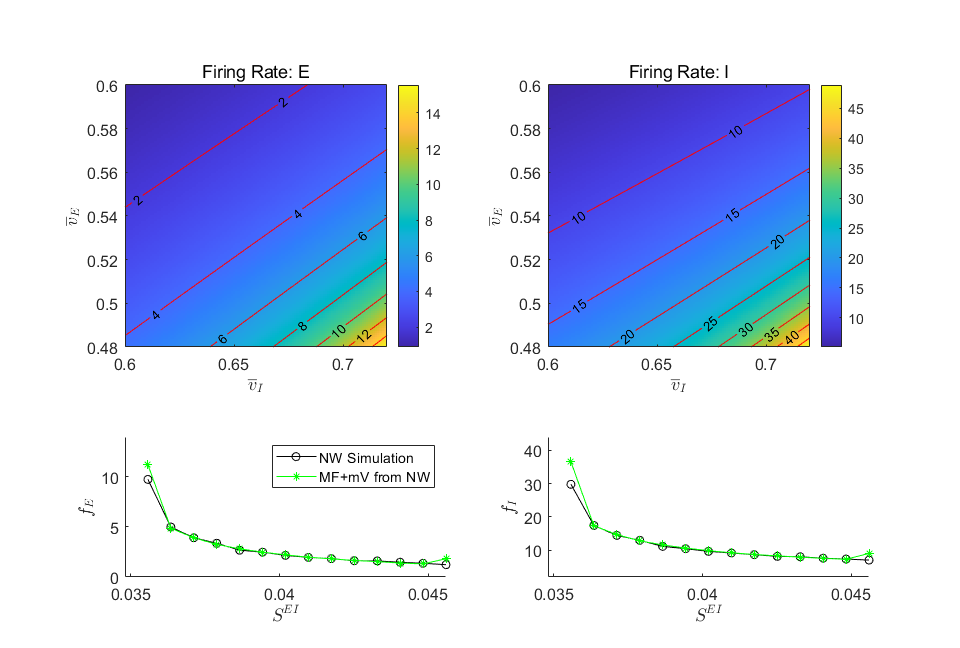

subplot(325)
hold on
%plot(S_EItest,Fr_Fix(1,:),'g')
%scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(1,:,1:MFSampleN)),...
%                                    length(S_EItest)*MFSampleN,1),'r.')
set(get(get(hebarE,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
plot(S_EItest,Fr_NW(1,:),'k','Marker','o','DisplayName','NW Simulation')
plot(S_EItest,Fr_OneStep(1,:),'g','Marker','*','DisplayName','MF+mV from NW')
xlabel('$$S^{EI}$$','Interpreter',"latex",'FontSize',12); 
ylabel('$$f_E$$','Interpreter',"latex",'FontSize',12)
ax1 = gca; ax1.FontSize = 12;
ax1 = gca; ax1.FontSize = 12;
legend
xlim([min(S_EItest) max(S_EItest)])
ylim([0 14])
ParameterDisp = ['S_{EE} = ' num2str(S_EE) ...
                         ', S_{IE} = ' num2str(S_IE) ', S_{II} = ' num2str(S_II) '\n' ...
                         'S_{Elgn} = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) '\n' ...
                         ', S_{Ilgn} = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
                         'S_{amb} = ' num2str(S_amb) ', rE_{amb} = ' num2str(rE_amb) ', rI_{amb} = ' num2str(rI_amb) '\n' ...
                         'S_{EL6} = ' num2str(S_EL6) ', S_{IL6} = ' num2str(S_IL6) 'r_{EL6} = ' num2str(rE_L6) ', r_{IL6} = ' num2str(rI_L6)  ];
titlePara = sprintf(ParameterDisp);
%title(titlePara)

subplot(3,2,6)
hold on
% plot(S_EItest,Fr_Fix(2,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(2,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
set(get(get(hebarI,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
plot(S_EItest,Fr_NW(2,:),'k','Marker','o')
plot(S_EItest,Fr_OneStep(2,:),'g','Marker','*')
xlabel('$$S^{EI}$$','Interpreter',"latex",'FontSize',12); 
ylabel('$$f_I$$','Interpreter',"latex",'FontSize',12)
ax1 = gca; ax1.FontSize = 12;
xlim([min(S_EItest) max(S_EItest)])
ylim([2 44])

FigM2 B and C

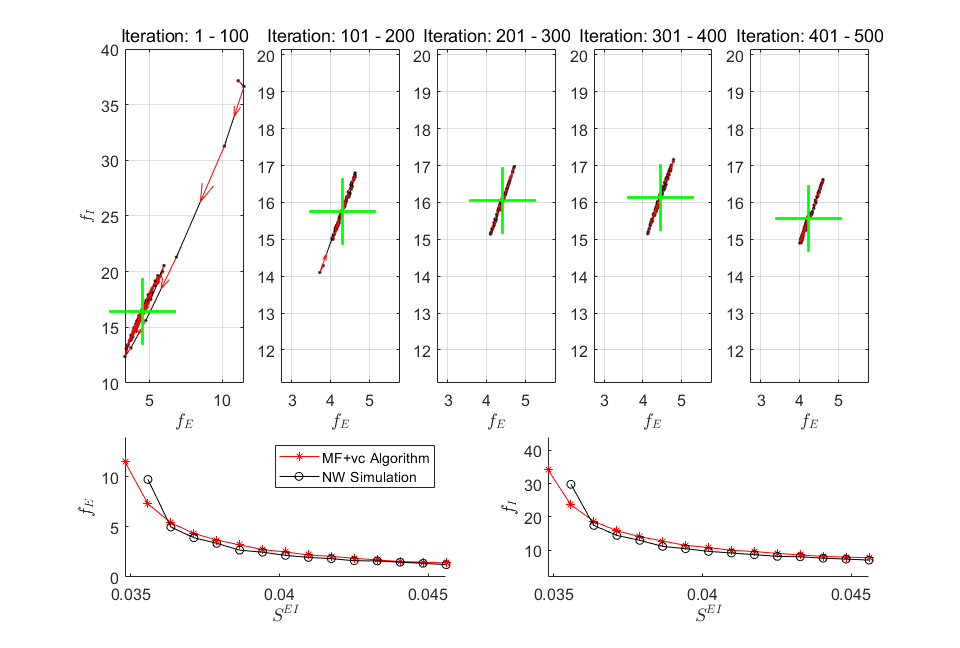

figure('Name','Method2','Units',"normalized",'OuterPosition',[0 0 0.5 0.6])
TrajInd = 4;
S_EI = S_EItest(TrajInd);
IteraN = 100;
TrajC = Fr_NoFixTraj_ref{TrajInd};
for TrajPanInd = 1:5 

subplot(3,5,[TrajPanInd,TrajPanInd+5])
plot_dir(TrajC(1, 1+(TrajPanInd-1)*IteraN : TrajPanInd*IteraN)',...
         TrajC(2, 1+(TrajPanInd-1)*IteraN : TrajPanInd*IteraN)');
hold on
plot(mean(TrajC(1, 1+(TrajPanInd-1)*IteraN : TrajPanInd*IteraN)), ...
     mean(TrajC(2, 1+(TrajPanInd-1)*IteraN : TrajPanInd*IteraN)),...
     'Marker','+','MarkerSize',50,'color','g','LineWidth',2)     
     
xlabel('$$f_E$$','Interpreter',"latex",'FontSize',12)
ax1 = gca; ax1.FontSize = 12;
title(sprintf('Iteration: %d - %d', 1+(TrajPanInd-1)*IteraN, TrajPanInd*IteraN))

if TrajPanInd>1
    axis([min(TrajC(1,IteraN:end))-1 max(TrajC(1,IteraN:end))+1 ...
          min(TrajC(2,IteraN:end))-3 max(TrajC(2,IteraN:end))+3])
else
    ylabel('$$f_I$$','Interpreter',"latex",'FontSize',12)
end
end

subplot 325
hold on
%plot(S_EItest,Fr_Fix(1,:),'g')
%scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(1,:,1:MFSampleN)),...
%                                    length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,Fr_NoFix_ref(1,:),'r','Marker','*','DisplayName','MF+vc Algorithm')
%hebarE = errorbar(S_EItest,Fr_NoFix_ref(1,:),Fr_NoFixVar_ref(1,:),'r.');
%set(get(get(hebarE,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
plot(S_EItest,Fr_NW(1,:),'k','Marker','o','DisplayName','NW Simulation')
xlabel('$$S^{EI}$$','Interpreter',"latex",'FontSize',12); 
ylabel('$$f_E$$','Interpreter',"latex",'FontSize',12)
ax1 = gca; ax1.FontSize = 12;
legend
xlim([min(S_EItest) max(S_EItest)])
ylim([0 14])
ParameterDisp = ['S_{EE} = ' num2str(S_EE) ...
                         ', S_{IE} = ' num2str(S_IE) ', S_{II} = ' num2str(S_II) '\n' ...
                         'S_{Elgn} = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) '\n' ...
                         ', S_{Ilgn} = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
                         'S_{amb} = ' num2str(S_amb) ', rE_{amb} = ' num2str(rE_amb) ', rI_{amb} = ' num2str(rI_amb) '\n' ...
                         'S_{EL6} = ' num2str(S_EL6) ', S_{IL6} = ' num2str(S_IL6) 'r_{EL6} = ' num2str(rE_L6) ', r_{IL6} = ' num2str(rI_L6)  ];
titlePara = sprintf(ParameterDisp);
%title(titlePara)

subplot 326
hold on
% plot(S_EItest,Fr_Fix(2,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(2,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,Fr_NoFix_ref(2,:),'r','Marker','*')
%hebarI = errorbar(S_EItest,Fr_NoFix_ref(2,:),Fr_NoFixVar_ref(2,:),'r.');
%set(get(get(hebarI,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
plot(S_EItest,Fr_NW(2,:),'k','Marker','o')
xlabel('$$S^{EI}$$','Interpreter',"latex",'FontSize',12); 
ylabel('$$f_I$$','Interpreter',"latex",'FontSize',12)
ax1 = gca; ax1.FontSize = 12;
xlim([min(S_EItest) max(S_EItest)])
ylim([2 44])